## Receiver Modelling

#### Approach #1                                                            Approach #2                                                                 Approach #3

 //Automatic Gain Control                                              //Phase and Polarisation Detection                                      //I/Q imbalance correction <-- appears in analog homodyne systems (maybe unnessesary)

 //Matched Filter to Tx (Raised Cosine)                        //ADC                                                                                    //Chromatic Dispersion compensation

 //Frequency compensation                                          //De-skew and orthonormalisation                                        //Clock Phase Recovery

 //Symbol Synchronisation                                            //Static Channel Equalisation                                               //Adaptive TDE MIMO-CMA

 //Carrier Synchronisation                                             //Dynamic Channel Equalisation                                          //Upsampling/Downsampling 

                                                                                     //Interpolation & Timing Recovery                                        //Carrier Frequency Recovery

                                                                                     //Frequency Estimation                                                        //Carrier Phase Recovery

                                                                                     //Carrier Phase Estimation

                                                                                     //Symbol Estimation and Decoding

## Definitions of constants/variables

%Resetting the rng seed
rng("default");
rng(1960);

num_symbols = 32*1024; 
PS = true;
%%Sets of signals to be manipulated in different ways
%These sets are also the SNR Values
sets = linspace(1,30,25);
num_sets = length(sets);

symbol_rate = 100e9; % GBaud  (This needs sampling of 200e9 Samples/s to satisfy Nyquist criterion)
time_step = 1/symbol_rate; %seconds
linewidth = 100e3; %Hz
variance=2*pi*linewidth*time_step;
rcos_tap_length = 32;

symbols = randi([0 1],1,num_symbols);

%%% Sampling notes: To remove aliasing effect from ADC we need 2x
%%% oversampling at 2/T. Meaning at symbol rate of 25GBd -> sampling rate
%%% of 50GS/s -> for QPSK, a rate of 100 Gb/s

## QPSK Modulation

modulated_symbols = pskmod(symbols,4,pi/4,'gray');
%demod_symbols = pskdemod(modulated_symbols,4,0,'gray');

figure
plot(modulated_symbols,'*','MarkerEdgeColor','black','MarkerFaceColor',"black");
title("QPSK modulated symbols");
xlabel("In-phase Amplitude");
ylabel("Quadrature Amplitude");
grid on;

## D/A Conversion

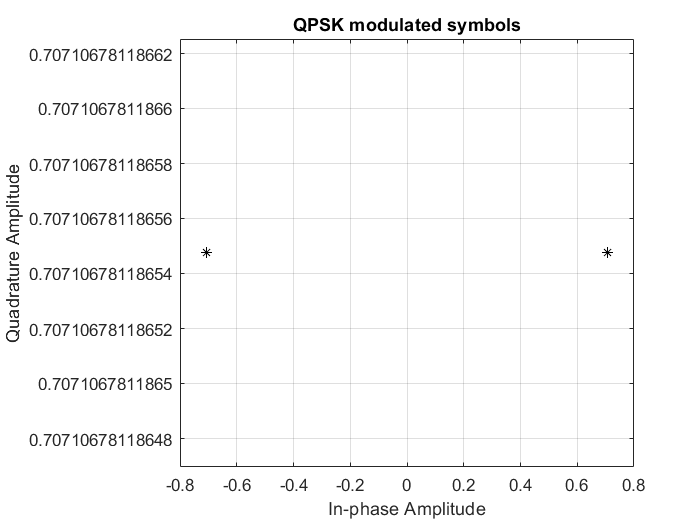

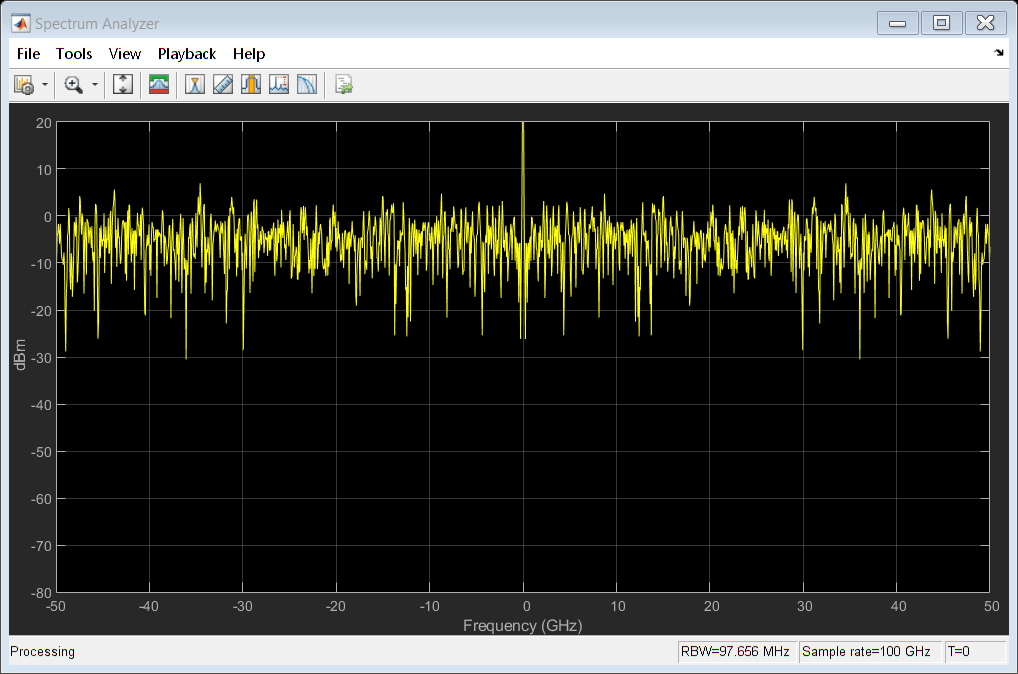

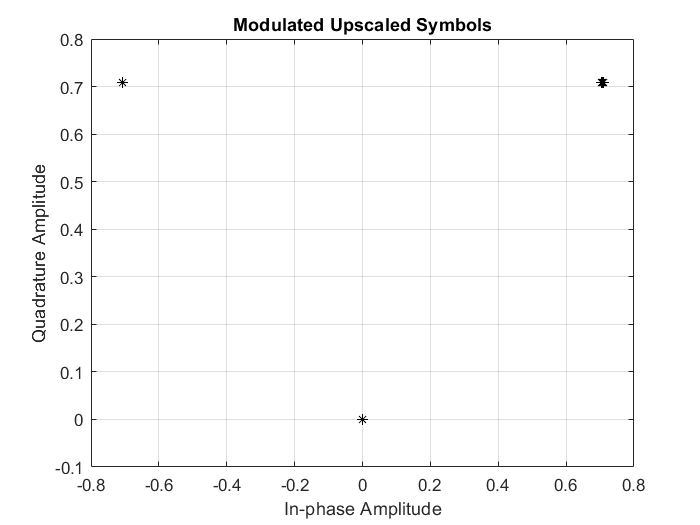

upscaling = 8;
Rolloff = 0.2;
sample_rate = symbol_rate*upscaling;
tx_ps_filter = comm.RaisedCosineTransmitFilter("FilterSpanInSymbols",rcos_tap_length,"OutputSamplesPerSymbol",upscaling,"RolloffFactor",Rolloff,"Shape","Square root","Gain",1);
rx_ps_filter = comm.RaisedCosineReceiveFilter("FilterSpanInSymbols",rcos_tap_length,"InputSamplesPerSymbol",upscaling,"RolloffFactor",Rolloff,"Shape","Square root","Gain",1);
%fvtool(tx_ps_filter)
filter_taps = coeffs(tx_ps_filter);
filter_taps = filter_taps.Numerator;

raised_cosine_scope = dsp.SpectrumAnalyzer('SampleRate',sample_rate);
matched_scope = dsp.SpectrumAnalyzer("SampleRate",symbol_rate);

mod_symbols = pskmod(symbols,4,pi/4,'gray'); %QPSK gray modulation

if PS
ps_symbols = tx_ps_filter(mod_symbols')';
matched_ps_symbols = rx_ps_filter(ps_symbols')';

%For spectrum measurements
raised_cosine_scope(ps_symbols');
matched_scope(matched_ps_symbols');


%ps_symbols = kron(mod_symbols,filter_taps);

num_samples = length(ps_symbols);

demoded_symbols = pskdemod(matched_ps_symbols,2);

plot(matched_ps_symbols,'*','MarkerEdgeColor','black');
title("Modulated Upscaled Symbols")
xlabel("In-phase Amplitude");
ylabel("Quadrature Amplitude");
grid on;
hold off;
else
num_samples = length(mod_symbols);
end

## AWGN and Phase Noise

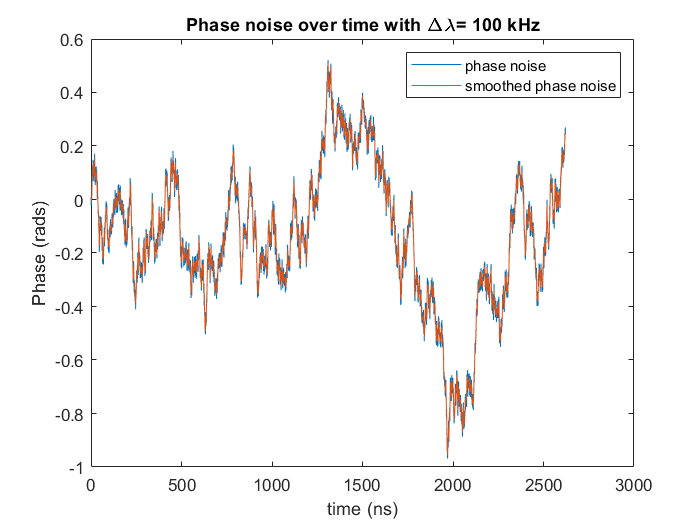

%%%Phase noise modeled as random walk%%%
% The cummulative sum of the standard deviations of each symbol's 
% phase as they are passed through the channel
rng(1960);

noise_sets = linspace(1,num_sets,num_sets);

phase_noise = randn(1,num_samples);

example_random_walk_phase_noise = cumsum(sqrt(variance).*phase_noise);

variances = (variance .* sets)';

phase_noise_sets = exp(1j*cumsum(sqrt(variances).* phase_noise));

t = (1:num_samples)*time_step*1e9; %in nanoseconds


figure
plot(t,example_random_walk_phase_noise,t,filtfilt(ones(100,1)/100,1,example_random_walk_phase_noise));
title('Phase noise over time with \Delta\lambda= 100 kHz');
xlabel("time (ns)");
ylabel("Phase (rads)");
legend("phase noise","smoothed phase noise");

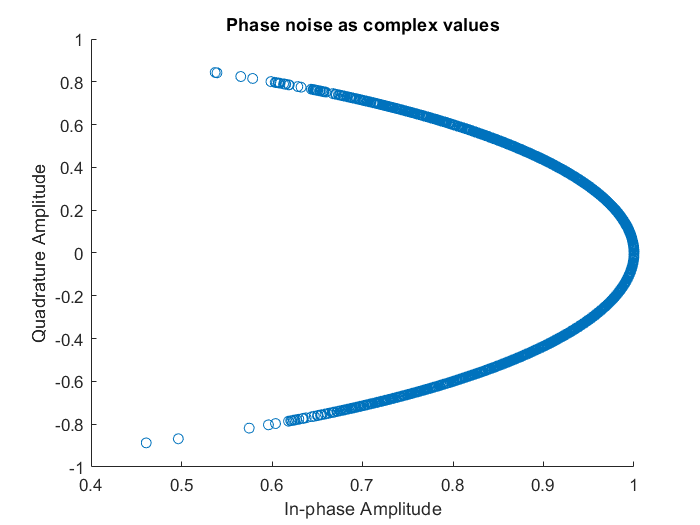



figure
scatter(real(phase_noise_sets(num_sets,:)),imag(phase_noise_sets(num_sets,:)));
title('Phase noise as complex values');
xlabel("In-phase Amplitude");
ylabel("Quadrature Amplitude");

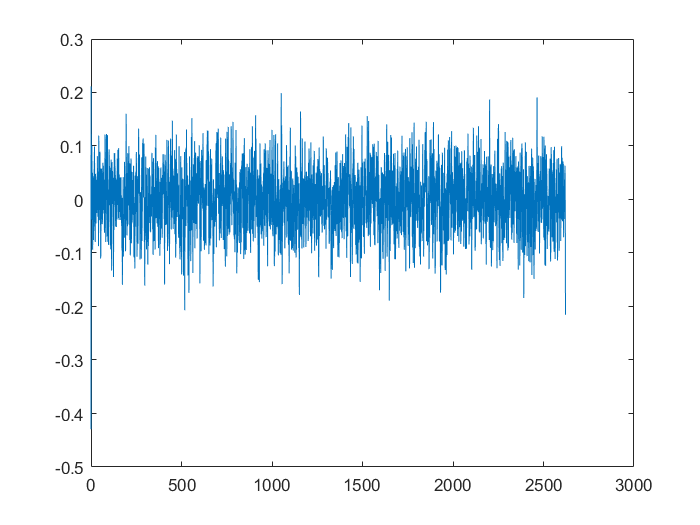


%%% Both phase and amplitude modified:
%phase_noise_sets = cumsum(sqrt(variances).*exp(1j*phase_noise));

%noisy_modulated_symbols = modulated_symbols .* phase_noise_sets;
%noisy_demod_symbols = pskdemod(noisy_modulated_symbols,4,0,"gray");

snr_values = sets;

awgn_symbol_sets = zeros(1,num_samples);

if PS
    for i=1:num_sets
        awgn_symbol_sets(i,:) = awgn(ps_symbols,snr_values(i));
    end

else
    for i=1:num_sets
        awgn_symbol_sets(i,:) = awgn(mod_symbols,snr_values(i));
    end
end

%%Add the largest phase noise and plot on the same graph for comparison
phase_awgn_symbol_sets = awgn_symbol_sets .* phase_noise_sets(num_sets,:);

%%Simple phase noise detection
%one-line approach
%phase_estimate = angle(-filtfilt(ones(100,1)/100,1,(phase_awgn_symbol_sets(30,:) .^ 4)))/4;

low_pass_filtered_noise = zeros(num_sets,num_samples);

raised_phase_sets = phase_awgn_symbol_sets.^4;

for i=1:num_sets
low_pass_filtered_noise(i,:) = filtfilt(ones(100,1)/100,1,raised_phase_sets(i,:));
end

phase_estimate = angle(-low_pass_filtered_noise)/4;

figure
plot(t,phase_estimate(num_sets,:));

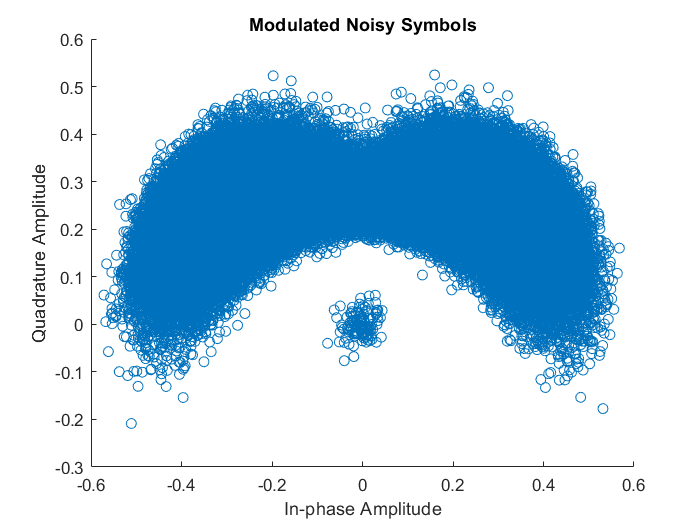


figure
scatter(real(phase_awgn_symbol_sets(num_sets,:)),imag(phase_awgn_symbol_sets(num_sets,:)));
title("Modulated Noisy Symbols");
xlabel("In-phase Amplitude");
ylabel("Quadrature Amplitude");

## A/D and QPSK Demodulation

if PS

automatic_gain_control = comm.AGC;
    
awgn_matched_sets = nan(num_sets,num_symbols);
phase_awgn_matched_sets = nan(num_sets,num_symbols);

for i=1:num_sets
    awgn_symbols = awgn_symbol_sets(i,:);
    awgn_symbols = automatic_gain_control(awgn_symbols')';   
    awgn_matched_sets(i,:) = rx_ps_filter(awgn_symbols')';
    
    phase_awgn_symbols = phase_awgn_symbol_sets(i,:);
    phase_awgn_symbols = automatic_gain_control(phase_awgn_symbols')';
    phase_awgn_matched_sets(i,:) = rx_ps_filter(phase_awgn_symbols')';
end

awgn_demod_symbol_sets = pskdemod(awgn_matched_sets,4,pi/4,"gray");

phase_awgn_demod_symbol_sets = pskdemod(phase_awgn_matched_sets,4,pi/4,"gray");

else
awgn_demod_symbol_sets = pskdemod(awgn_symbol_sets,4,pi/4,'gray');
phase_awgn_demod_symbol_sets = pskdemod(phase_awgn_symbol_sets,4,pi/4,'gray');
end

## SNR and BER

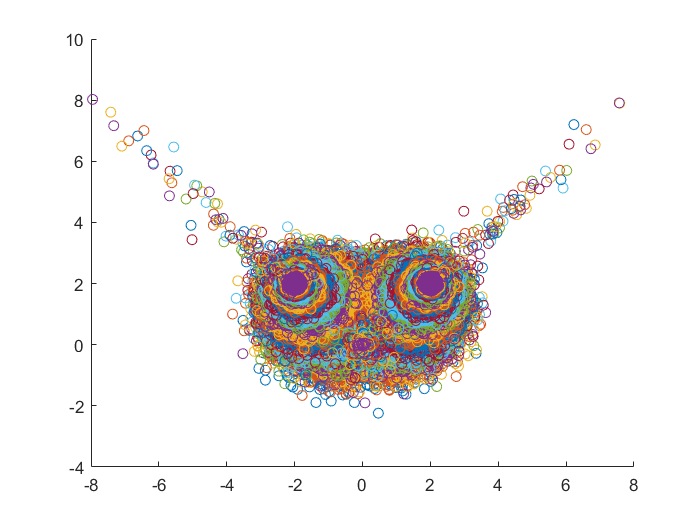

[~,AWGN_BER] = biterr(symbols(1:end-rcos_tap_length),awgn_demod_symbol_sets(num_sets,1+rcos_tap_length:end),2);
[~,PHASE_AWGN_BER] = biterr(symbols,phase_awgn_demod_symbol_sets,2);

if PS
figure
for i=1:25
scatter(real(awgn_matched_sets(i,:)),imag(awgn_matched_sets(i,:)));
hold on
end
end

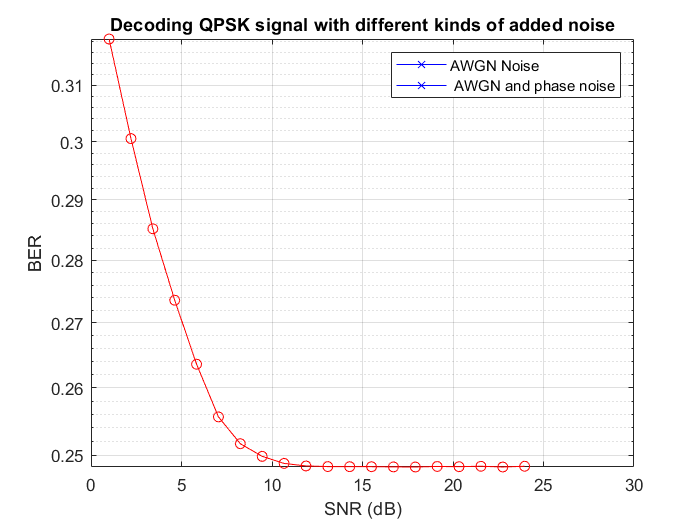


figure
semilogy(snr_values,AWGN_BER,"-bx");
title("Decoding QPSK signal with different kinds of added noise");
grid on ;
xlabel("SNR (dB)");
ylabel("BER");
hold on ;
semilogy(snr_values(1,1:20),PHASE_AWGN_BER(1:20,1),"ro-");
legend("AWGN Noise"," AWGN and phase noise");
hold off;

## Spectral Analysis

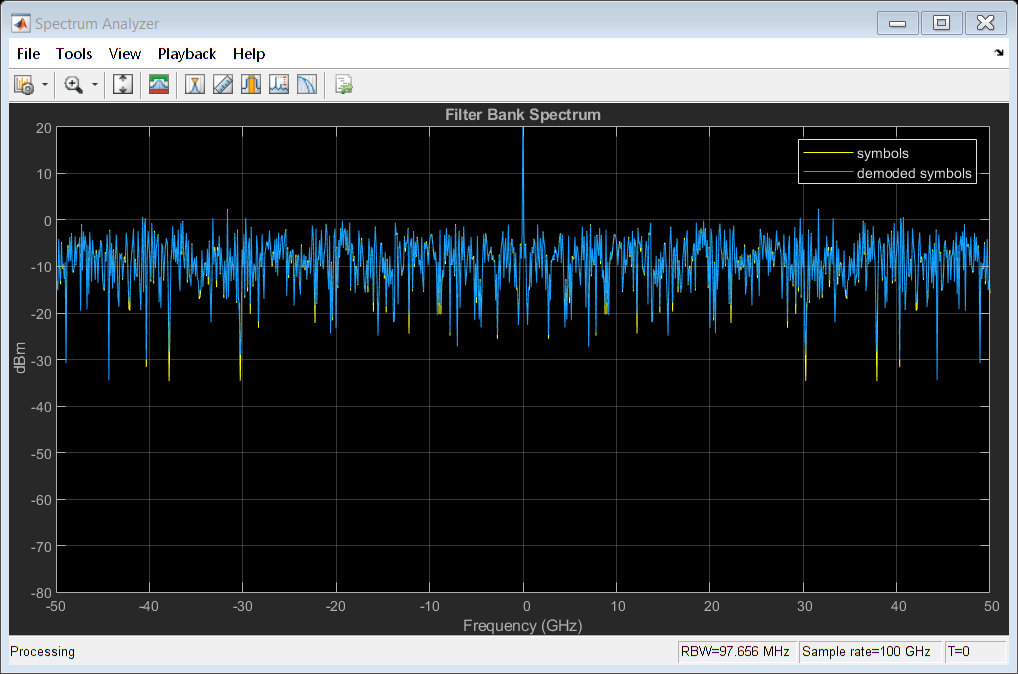

%%%%Creating an FFT using the Filter Bank Method
spectrum_scope = dsp.SpectrumAnalyzer( ...
    'NumInputPorts', 2, ...
    'ChannelNames', {'repeated symbols','pulse-shaped symbols'}, ...
    'SampleRate',symbol_rate, ...
    'Method','Filter bank', ...
    'PlotAsTwoSidedSpectrum',true, ...
    'FrequencyResolutionMethod','NumFrequencyBands', ...
    'FFTLengthSource','Property', ...
    'FFTLength',1024, ...
    'SpectralAverages',1, ...
    'Title','Filter Bank Spectrum', ...
    'ShowLegend',true);

upscaled_symbols = kron(symbols,ones(1,upscaling));


spectrum_scope(upscaled_symbols',ps_symbols');
release(spectrum_scope);

spectrum_scope = dsp.SpectrumAnalyzer( ...
    'NumInputPorts', 2, ...
    'ChannelNames', {'symbols','demoded symbols'}, ...
    'SampleRate',symbol_rate, ...
    'Method','Filter bank', ...
    'PlotAsTwoSidedSpectrum',true, ...
    'FrequencyResolutionMethod','NumFrequencyBands', ...
    'FFTLengthSource','Property', ...
    'FFTLength',1024, ...
    'SpectralAverages',1, ...
    'Title','Filter Bank Spectrum', ...
    'ShowLegend',true);

spectrum_scope(symbols',awgn_demod_symbol_sets(num_sets,:)');   

## **Plotting remnants**

%{
function no_out = plotting(variance, phase_noise, sets, modulated_symbols, symbols)

sets_num = length(sets);

figure
plot(cumsum(sqrt(variance).*phase_noise))
title('phase noise as random walk')

variances = (variance .* sets)';
phase_noise_sets = exp(1j*cumsum(sqrt(variances).*phase_noise));

phase_noise_only_modsym = modulated_symbols .* phase_noise_sets;
phase_noise_only_demodsym = pskdemod(phase_noise_only_modsym,4,0,"gray");

figure
for i=1:sets_num
    hold on
    scatter(real(phase_noise_only_modsym(i,:)),imag(phase_noise_only_modsym(i,:)));
end
title("Noisy Modulated Symbols passed through Channel")
xlabel("In-phase Amplitude")
ylabel("Quadrature Amplitude")
hold off

%{
figure
scatter(real(noisy_demod_symbols),imag(noisy_demod_symbols),"filled","d")
title("Demodulated Noisy Symbols 'passed' through Channel")
%}

figure
plot(phase_noise_only_demodsym,symbols,"rs")
title("Transmitted Symbols against Received Symbols")
xlabel("For perfect demodulation there should only be squares on (0,0),(1,1),(2,2),(3,3)")
plot(modulated_symbols)
axis([0,4,0,4])
grid on
no_out=phase_noise_only_demodsym(1,1);
end
%}